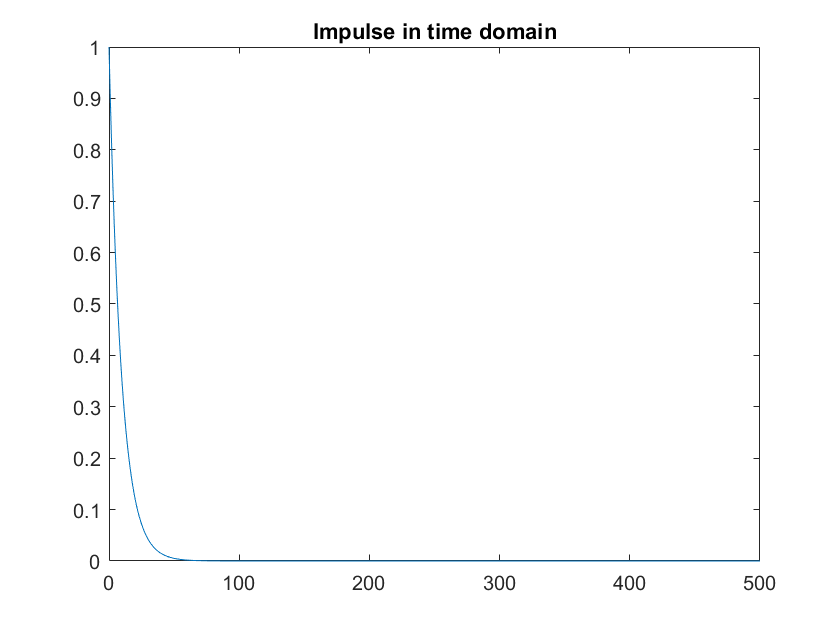

% IDTFT test
n=500;
n=0:n;
K=250;
% k=-K:K;
% w=(k/K)*pi;
h=0.9.^abs(n); 
figure("Name",'Impulse in time domain')
plot(n,h);
title('Impulse in time domain')

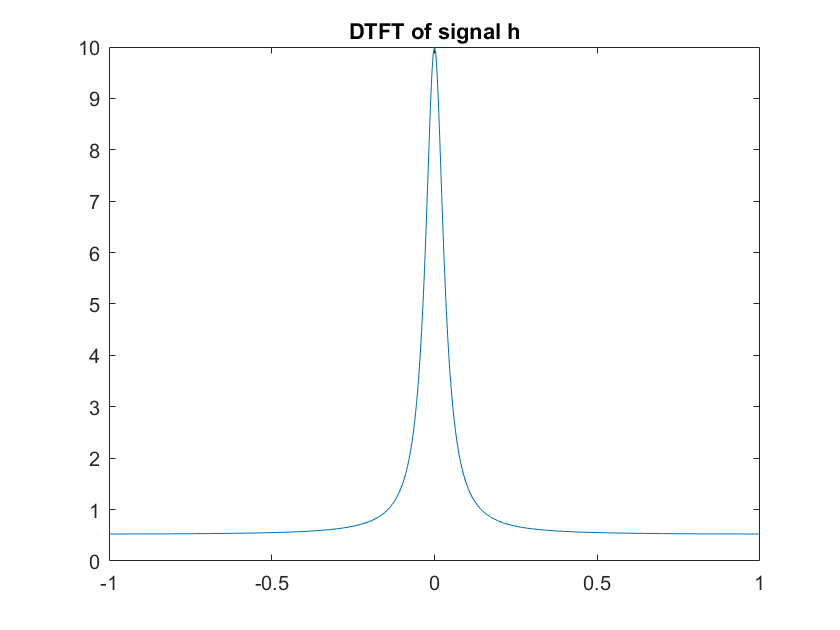


[H,w]=dtft(h,n,K);
% H=fft(h,501)
% Hf=circshift(H,ceil(length(n)/2))
figure("Name",'DTFT')
plot(w/pi,real(H));
title('DTFT of signal h')

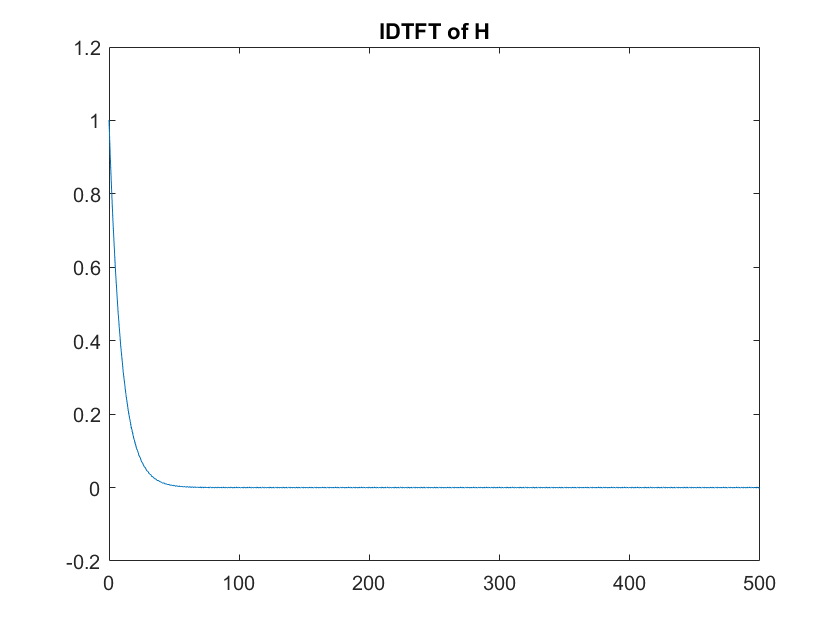


[ht,nt]=idtft(H,n,K);
% ht=ifft(H,length(n))
% ht(450:501)=0; 

figure("Name",'IDTFT')
plot(nt,real(ht));
title('IDTFT of H')



% error=max(abs(real(h)/max(real(h))-real(ht)/max(real(ht))))
error=(max(abs(real(h)-real(ht)))),%/max(real(h))

error = 0.0011